% List of Gear and Bearing widths (in Inches)
Gearwidth_2_3 = 1.5; % Width of gear 2 and gear 3
Gearwidth_4_5 = 2; % Width of gear 4 and gear 5
Outside_Bearing = 1; % Width of the bearings outside of the gears
Inside_Bearing = 0.75; % Width of the bearings on the inside next to gear 2 and gear 5
Shaft_Length = 11.5; % Total Shaft Length

**Sketch of Shaft Layout:**

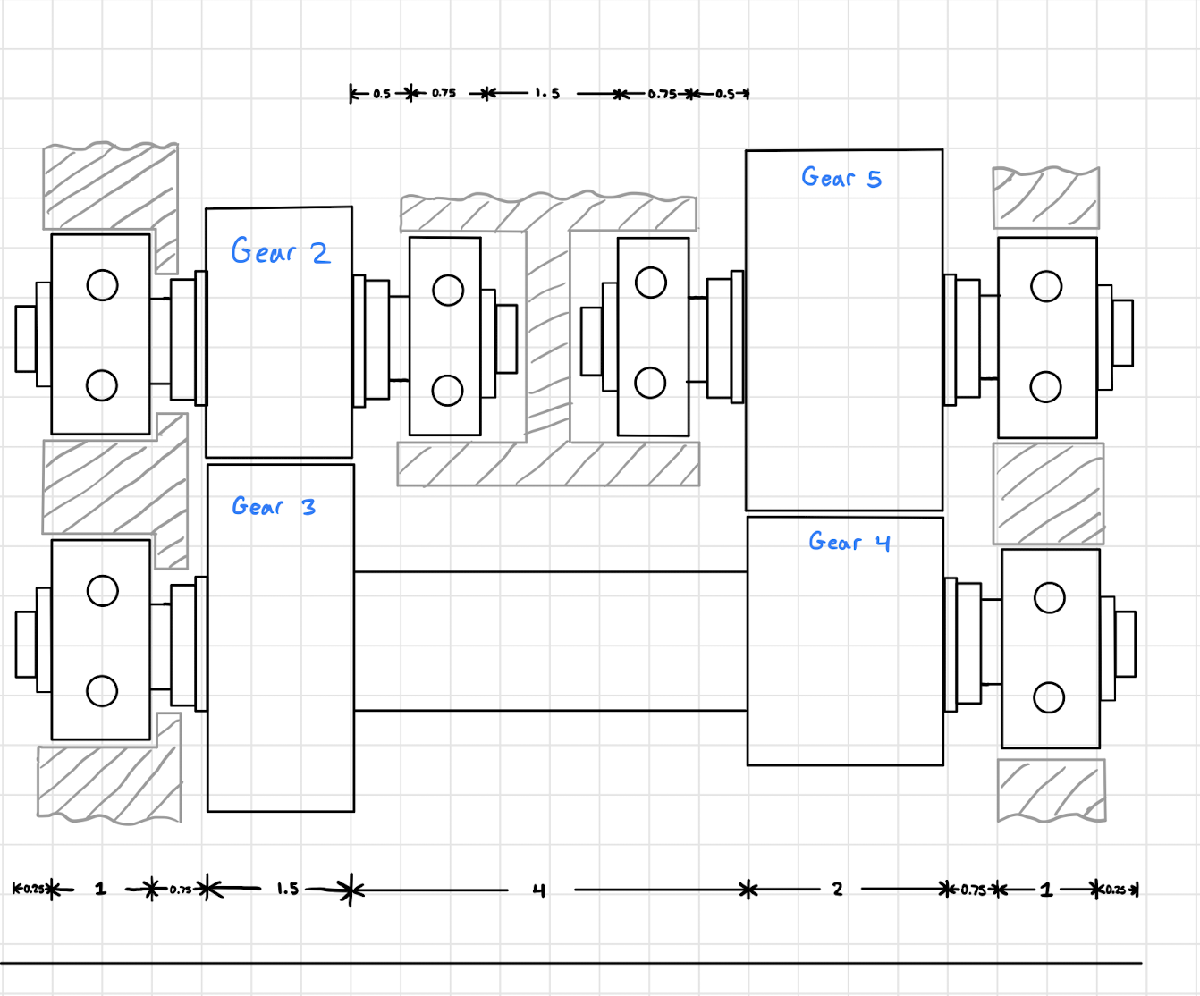

% Calculationg Center Locations of Bearings and Gears measured from the left hand side of the shaft (LHS will be used as the 0 point)
% Locations are calculated in inches.
Bearing_2_Out = 0.25 + Outside_Bearing/2; % Bearing on the LHS of Gear 2
Bearing_3_Out = 0.25 + Outside_Bearing/2; % Bearing on the LHS of Gear 3
Bearing_2_In = 0.25 + Outside_Bearing + 0.5 + Inside_Bearing/2; % Bearing on the RHS of Gear 2
Gear_2 = 0.25 + Outside_Bearing + 0.75 + Gearwidth_2_3/2; % Gear 2
Gear_3 = 0.25 + Outside_Bearing + 0.75 + Gearwidth_2_3/2; % Gear 3
Bearing_4_Out = Shaft_Length - (0.25 + Outside_Bearing/2); % Bearing on the RHS of Gear 4
Bearing_5_Out = Shaft_Length - (0.25 + Outside_Bearing/2); % Bearing on the RHS of Gear 5
Bearing_5_In = Shaft_Length - (0.25 + Outside_Bearing + 0.5 + Inside_Bearing/2); % Bearing on the LHS of Gear 5
Gear_4 = Shaft_Length - (0.25 + Outside_Bearing + 0.75 + Gearwidth_4_5/2); % Gear 4
Gear_5 = Shaft_Length - (0.25 + Outside_Bearing + 0.75 + Gearwidth_4_5/2); % Gear 5

% Creating Table Listing Bearing Center Locations
Bearing_Names = ['Bearing on LHS of Gear 2'; 'Bearing on RHS of Gear 2'; 'Bearing on LHS of Gear 3'; 'Bearing on RHS of Gear 4'; 'Bearing on LHS of Gear 5'; 'Bearing on RHS of Gear 5'];
Bearings = [Bearing_2_Out; Bearing_2_In; Bearing_3_Out; Bearing_4_Out; Bearing_5_In; Bearing_5_Out];
Table1=table(Bearing_Names, Bearings);

% Creating Table Listing Gear Locations
Gear_Names = ['Gear 2'; 'Gear 3'; 'Gear 4'; 'Gear 5'];
Gear = [Gear_2; Gear_3; Gear_4; Gear_5];
Table=table(Gear_Names, Gear);

% Displaying Tables
Table1.Properties.VariableNames={'Bearing', 'Location of the Center Measured from LHS of the Shaft (Inches)'}

Table1 = 6×2 table
            Bearing             Location of the Center Measured from LHS of the Shaft (Inches)
    ________________________    ______________________________________________________________

    Bearing on LHS of Gear 2                                 0.75                             
    Bearing on RHS of Gear 2                                2.125                             
    Bearing on LHS of Gear 3                                 0.75                             
    Bearing on RHS of Gear 4                                10.75                             
    Bearing on LHS of Gear 5                                9.375                             
    Bearing on RHS of Gear 5                                10.75                             


Table.Properties.VariableNames={'Gear', 'Location of the Center Measured from LHS of the Shaft (Inches)'}

Table = 4×2 table
     Gear     Location of the Center Measured from LHS of the Shaft (Inches)
    ______    ______________________________________________________________

    Gear 2                                 2.75                             
    Gear 3                                 2.75                             
    Gear 4                                  8.5                             
    Gear 5                                  8.5                             
